# Lecture 17 - Beam

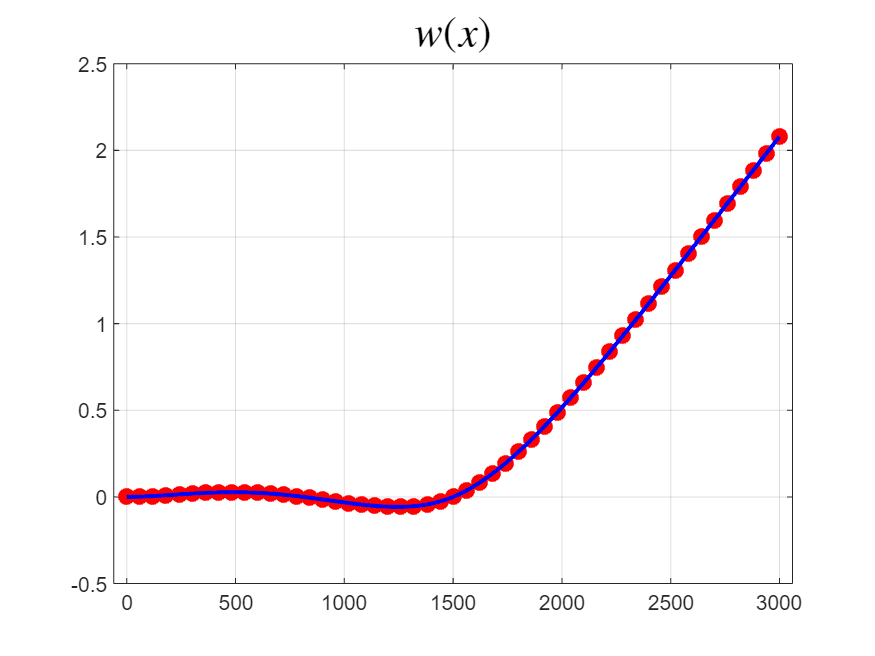

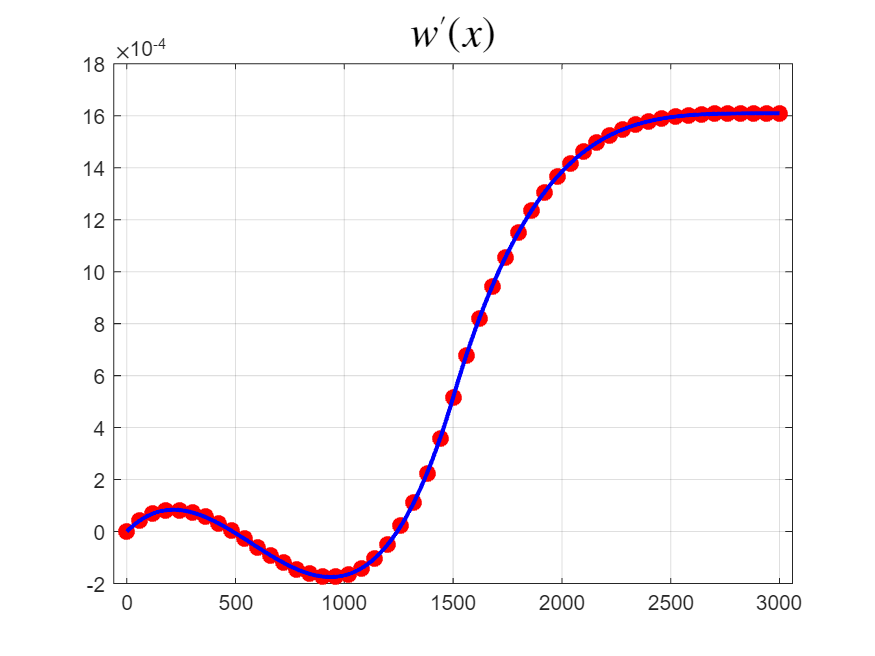

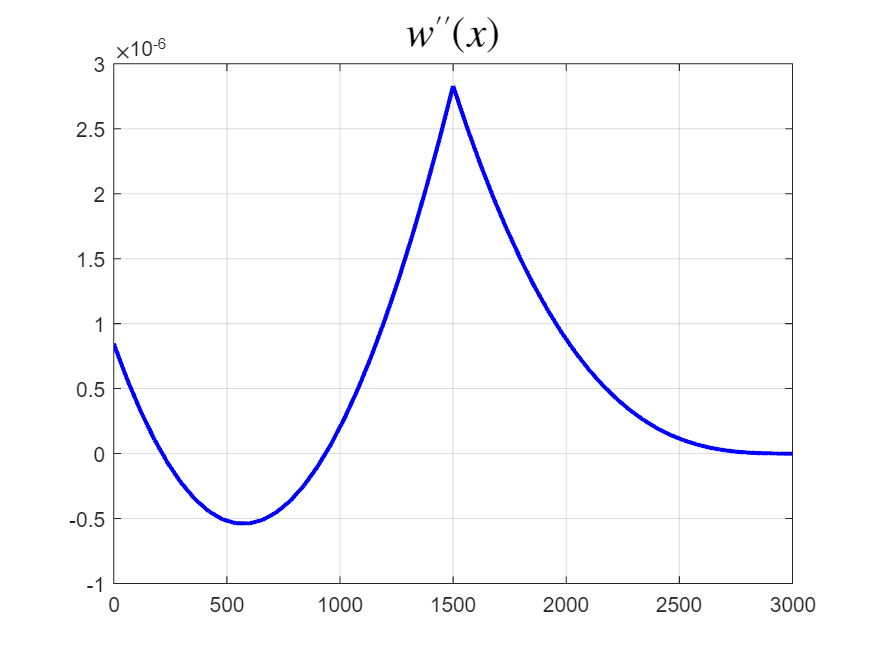

ans = 457

e = 8

xej =    420   480


Delej =     0.0257
   -0.0000
    0.0268
   -0.0000


wex_ = 0.0266

dwedx_ = 1.5156e-05

d2wedx2_ = -4.8207e-07

ans = 1731

e = 29

xej =         1680        1740


Delej =     0.1338
   -0.0009
    0.1938
   -0.0011


wex_ = 0.1844

dwedx_ = 0.0010

d2wedx2_ = 1.7520e-06

clear; clc; close all

[Delg, x, w, dwdx, d2wdx2] = FEA(50, 30);

function [Delg, x, w, dwdx, d2wdx2] = FEA(N, ptsEL)

    E=200000; % in MPa
    I=29*10^6; % in mm^4
    EI=E*I;
    q0=50;    %
    F0=0; % in N
    M0=0; 
    L=3000; % in mm
 
    p=2;

    he=L/N; %Geometric parameter
    w0=0; dwdx0=0; %Essential BCs

    TotalDoFs = 2*N*(p-1)+2; %TotalNodes and TotalDoFs
    

    if(mod(N, 2)==1)
        midUDoF = TotalDoFs/2+1;
    else
        midUDoF = TotalDoFs/2;
    end
    Essential_BC_DoFs = [1, 2, midUDoF];
    Essential_BCs = [w0, dwdx0];

    Natural_BC_DoFs = [TotalDoFs-1, TotalDoFs];
    Natural_BCs = [F0, -M0];

    r = length(Essential_BC_DoFs);
    s = length(Natural_BC_DoFs);


    Qg = zeros(TotalDoFs, 1);
    for i=1:s
        DoF = Natural_BC_DoFs(i);
        Qg(DoF) = Natural_BCs(i);
    end

    Delg = zeros(TotalDoFs, 1);
    for i=1:s
        DoF = Essential_BC_DoFs(i);
        Delg(DoF) = Essential_BCs(i);
    end
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %%%%% ASSEMBLY %%%%%%   
    EIe = EI; cfe = 0;
    Kg = zeros(TotalDoFs);
    fg = zeros(TotalDoFs, 1);

    for e=1:N
        xe = (e-1)*he + he/2; % xe is the position of the element centre
        qe = q0*(1-(xe/L)^2);
        [Ke, fe] = EM(EIe, cfe, qe, he);

        for i=1:2*p
            I = 2*(e-1)*(p-1)+i;
            fg(I) = fg(I) + fe(i);
            for j=1:2*p
                J = 2*(e-1)*(p-1)+j;
                Kg(I, J) = Kg(I, J) +  Ke(i, j);
            end
        end
    end
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %%%%% CONDENSATION %%%%%
    Kc = Kg; fc = fg - Kg*Delg; Qc = Qg; DelcRows = 1:TotalDoFs;
    Kc(Essential_BC_DoFs, :) = [];
    Kc(:, Essential_BC_DoFs) = [];
    fc(Essential_BC_DoFs) = [];
    Qc(Essential_BC_DoFs) = [];
    DelcRows(Essential_BC_DoFs) = [];
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %%%%%% Solving the matrix Equation %%%%%%
    Delc = linsolve(Kc, Qc+fc);

    for i=1:(TotalDoFs-r)
        Delg(DelcRows(i)) = Delc(i);
    end
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%% VISUALIZATION %%%%%%
    [x, w, dwdx, d2wdx2] = wSol(Delg, N, he, ptsEL);

% subplot(3, 1, 1);
figure;
    xVec = linspace(0, L, TotalDoFs/2);
    plot(xVec, Delg(1:2:TotalDoFs), ".", MarkerSize=24, Color="red")
    xlim([0-he, L+he]);
    title("$w(x)$", Interpreter="latex", FontSize=20);
    hold on; grid on;
    plot(x, w, LineWidth=2, Color="blue");


  % subplot(3, 1, 2);
  figure;
    plot(xVec, -Delg(2:2:TotalDoFs), ".", MarkerSize=24, Color="red")
    xlim([0-he, L+he]);
    title("$w'(x)$", Interpreter="latex", FontSize=20);
    hold on; grid on;
    plot(x, dwdx, LineWidth=2, Color="blue");



  % subplot(3, 1, 3);
  figure;
    xlim([0-he, L+he]);
    plot(x, d2wdx2, LineWidth=2, Color="blue");
    title("$w''(x)$", Interpreter="latex", FontSize=20);
    grid on;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%% OBTAINING SOLUTION AT A PARTICULAR LOCATION %%%%%%%%%%
    
    xLoc = [457, 1731];

    for i=1:length(xLoc)
        xLoc(i)
        e = ceil(xLoc(i)/he) % element number
        xej = [xVec(e), xVec(e+1)]
        Delej = [Delg(2*(p-1)*(e-1)+1: 2*(p-1)*(e-1)+4)]
        wex_ = wex(xLoc(i), xej, Delej)
        dwedx_ = dwedx(xLoc(i), xej, Delej)
        d2wedx2_ = d2wedx2(xLoc(i), xej, Delej)
    end
    

 end

#### Function to evaluate element matrices

function [Ke, fe] = EM(EIe, cfe, qe, he)
    T1 = [[6,-3*he,-6,-3*he];[-3*he,2*he^2,3*he,he^2];[-6,3*he,6,3*he];[-3*he,he^2,3*he,2*he^2]];
    T2 = [[156,-22*he,54,13*he];[-22*he,4*he^2,-13*he,-3*he^2]; [54,-13*he,156,22*he]; [13*he,-3*he^2,22*he,4*he^2]] ;
    Ke = 2*EIe/he^3*T1 + cfe*he/420*T2 ;

    T3 = [6; -he; 6; he];
    fe = qe*he/12*T3;
end


#### Functions for post-processing

function out = wex(x, xej, Delej)
    p = length(xej);
    he = xej(p) - xej(1);
    xbar = (x-xej(1))/he;

    phi0 = 1-3*xbar.^2+2*xbar.^3;
    phi1 = -he*xbar.*(1-xbar).^2;
    phi2 = 3*xbar.^2-2*xbar.^3;
    phi3 = -he*xbar.*(xbar.^2-xbar);

    phiVec=[phi0,phi1,phi2,phi3];

    out = zeros(length(xbar), 1);
    for i=1:length(xbar)
        out(i) =phiVec(i, :)*Delej;
    end
    
end

function out = dwedx(x, xej, Delej)
    p = length(xej);
    he = xej(p) - xej(1);
    xbar = (x-xej(1))/he;

    dphi0dx = -6*xbar/he+6*xbar.^2/he;
    dphi1dx = -(1-xbar).^2 + xbar.*2.*(1-xbar);
    dphi2dx = 6*xbar/he-6*xbar.^2/he;
    dphi3dx = -(xbar.^2-xbar) -xbar.*(2.*xbar-1);

    dphidxVec=[dphi0dx,dphi1dx,dphi2dx,dphi3dx];  

    out = zeros(length(xbar), 1);
    for i=1:length(xbar)
        out(i) =dphidxVec(i, :)*Delej;
    end
end

function out = d2wedx2(x, xej, Delej)
    p = length(xej);
    he = xej(p) - xej(1);
    xbar = (x-xej(1))/he;

    d2phi0dx2 = -6/he.^2+12*xbar/he.^2;
    d2phi1dx2 = 2*(1-xbar)/he + 2/he - 4*xbar/he;
    d2phi2dx2 = 6/he.^2-12*xbar/he.^2;
    d2phi3dx2 = -(2*xbar/he-1/he) -4*xbar/he + 1/he;

    d2phidx2Vec=[d2phi0dx2,d2phi1dx2,d2phi2dx2,d2phi3dx2]; 

    out = zeros(length(xbar), 1);
    for i=1:length(xbar)
        out(i) = d2phidx2Vec(i, :)*Delej;
    end
end


function [Mat1, Mat2, Mat3, Mat4] = wSol(Delg, N, he, ptsEL)
    p=2;
    Mat1 = double.empty;
    Mat2 = Mat1;
    Mat3 = Mat1;
    Mat4 = Mat1;
    
    for e=1:N
        xej = linspace(he*(e-1), he*e, 2);
        Delej = Delg((e-1)*(p-1)*2+1:((e)*(p-1)*2+2));

        x = linspace(xej(1), xej(2), ptsEL)';
        
        w = wex(x, xej, Delej);
        dwdx = dwedx(x,xej,Delej);
        d2wdx2 = d2wedx2(x,xej,Delej);

        Mat1 = [Mat1, x];
        Mat2 = [Mat2, w];
        Mat3 = [Mat3, dwdx];
        Mat4 = [Mat4, d2wdx2];
    end
end